clear; close all; clc;
set(groot, 'defaultLegendInterpreter','latex'); 

## Defining Physical Parameters and Sensor Gains

The following lines of code will define the sensor gains and physical parameters used for the simulation.

Ka     = 5.5;     % Power Amplifier
N      = 8.1;        % Speed Reduction Factor
Km     = 22.289;     % Motor gain [rad/s/V]
Km_lin = 19.763;     % Linearized motor gain [rad/s/V]
tau_m  = .2740;      % Motor time constant [s]
Kp     = 4.90379;    % Position Feedback Gain
Kt     = .1429;
vmo    = 0.66;       % Voltage to hold pendulum at 90 degrees [V]
g      = 9.81;       % gravitational acceleration [m/s/s]

#### Defining physical parameters of the pendulum

L = 0;      % Pendulum rod length [in]
m = 0; % Bob mass [kg]
physParam = [m, L, g, vmo, N, Km_lin];

The next line will define the intial condition of the pendulum

th_init = deg2rad(10);
Vin = 1.53;

simout = sim('motomatic_pend_OL.slx',2);
speed = readtable("Step1Orig.csv");

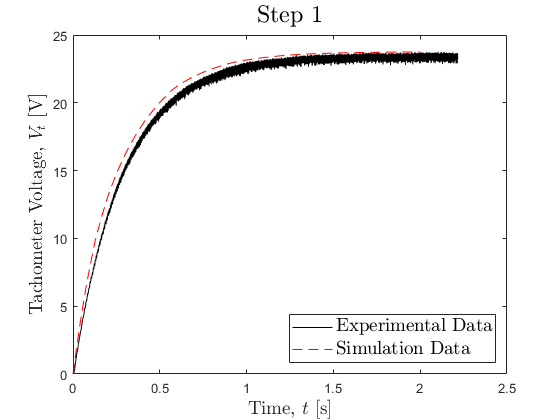

figure;
plot(speed.Time_s_,speed.Math1_V_,'k');
hold on
plot(simout.tout, simout.vt,'r--')
hold off
xlabel('Time, $t$ [s]','Interpreter','Latex','FontSize',14); 
ylabel('Tachometer Voltage, $V_t$ [V]','Interpreter','Latex','FontSize',14);
xlim([0 2.5]); ylim([0 25]);
title('Step 1','Interpreter','Latex','FontSize',18)
legend('Experimental Data','Simulation Data','location','southeast','fontsize',14);


Vin = 1.6;

simout = sim('motomatic_pend_OL.slx',2);
speed = readtable("Step2Orig.csv");

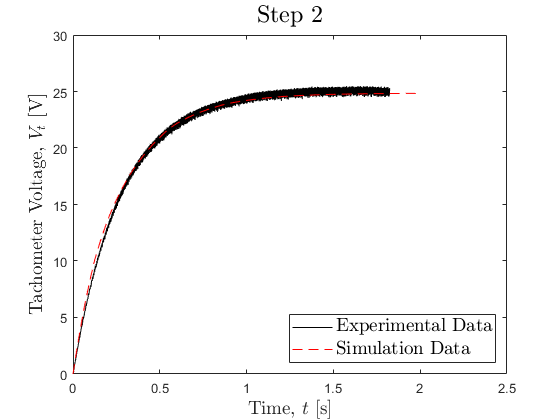

figure;
plot(speed.Time_s_,speed.Math1_V_,'k');
hold on
plot(simout.tout, simout.vt,'r--')
hold off
xlabel('Time, $t$ [s]','Interpreter','Latex','FontSize',14); 
ylabel('Tachometer Voltage, $V_t$ [V]','Interpreter','Latex','FontSize',14);
xlim([0 2.5]); ylim([0 30]);
title('Step 2','Interpreter','Latex','FontSize',18)
legend('Experimental Data','Simulation Data','location','southeast','fontsize',14);



Vin = 1.06;

simout = sim('motomatic_pend_OL.slx',2);
speed = readtable("Step3Orig.csv"); 

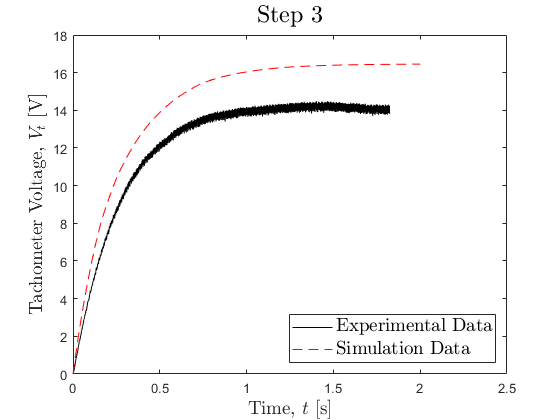

figure;
plot(speed.Time_s_,speed.Math1_V_,'k');
hold on
plot(simout.tout, simout.vt,'r--')
hold off
xlabel('Time, $t$ [s]','Interpreter','Latex','FontSize',14); 
ylabel('Tachometer Voltage, $V_t$ [V]','Interpreter','Latex','FontSize',14);
xlim([0 2.5]);
title('Step 3','Interpreter','Latex','FontSize',18)
legend('Experimental Data','Simulation Data','location','southeast','fontsize',14);

SSdata = readtable("SSdata.xlsx")

SSdata = 11×5 table
    MotorSpeed     Rad        Vo        Vm       VT  
    __________    ______    ______    ______    _____

          0            0         0    -0.025        0
        650       68.068    -0.873      4.25     -9.8
        900       94.248    -1.061      5.36    -13.5
       1450       151.84    -1.463       7.6    -21.4
       1800        188.5    -1.762      9.26    -27.1
       2200       230.38     -2.04     10.86      -33
        NaN          NaN    -0.223    -0.774      NaN
        245       25.656    -0.463      2.06     -3.6
        140       14.661    -0.368      1.56    -1.65
          0            0    -0.271      1.07        0
         60       6.2832     -0.32       1.3    -1.01


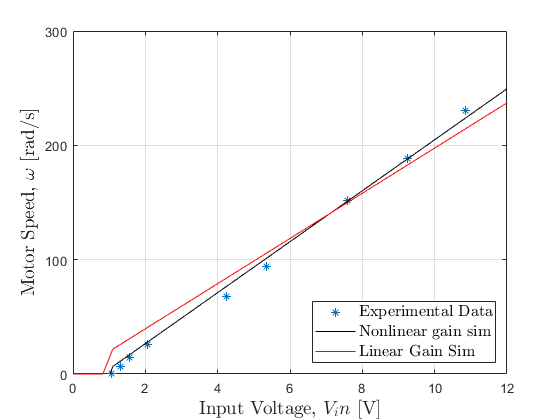

myVm = [];
myVmLin = [];
i=1;
physParam = [m, L, g, vmo, N, Km];
for Vin = 0:.05:2.5
    simout = sim('motomatic_pend_OL.slx',4);
    myVm(i,1) = simout.vm(length(simout.vm));
    myVm(i,2) = max(simout.X(:,2))*N;
    i = i+1;
end
physParam = [m, L, g, vmo, N, Km_lin];
for Vin = 0:.05:2.5
    simout = sim('motomatic_pend_OL.slx',4);
    myVmLin(i,1) = simout.vm(length(simout.vm));
    myVmLin(i,2) = max(simout.X(:,2))*N;
    i = i+1;
end
figure;
plot(SSdata.Vm,SSdata.Rad,'*');
hold on
plot(myVm(:,1),myVm(:,2)-18,'k');
plot(myVmLin(:,1),myVmLin(:,2),'r');
hold off
grid on; box on;
xlabel('Input Voltage, $V_in$ [V]','Interpreter','Latex','FontSize',14); 
ylabel('Motor Speed, $\omega$ [rad/s]','Interpreter','Latex','FontSize',14);
xlim([0 12]);xticks([0:2:12]);
ylim([0 300]); yticks([0:100:300]);
legend('Experimental Data','Nonlinear gain sim','Linear Gain Sim','location','southeast','fontsize',12);

Vin = 1.03;
Vpdata = readtable("PositionSensorOrig.csv")

Vpdata = 8000×3 table
    Time_s_     Channel2_V_    Math1_V_
    ________    ___________    ________

        -0.2      1.0315       -14.077 
    -0.19975      1.0348       -14.063 
     -0.1995      1.0348       -14.056 
    -0.19925      1.0415       -14.053 
      -0.199      1.0415        -14.04 
    -0.19875      1.0415       -14.013 
     -0.1985      1.0382       -13.942 
    -0.19825      1.0348       -13.892 
      -0.198      1.0382       -13.878 
    -0.19775      1.0348       -13.865 
     -0.1975      1.0348       -13.855 
    -0.19725      1.0382       -13.845 
      -0.197      1.0348       -13.828 
    -0.19675      1.0348       -13.814 
     -0.1965      1.0382       -13.798 
    -0.19625      1.0348       -13.787 


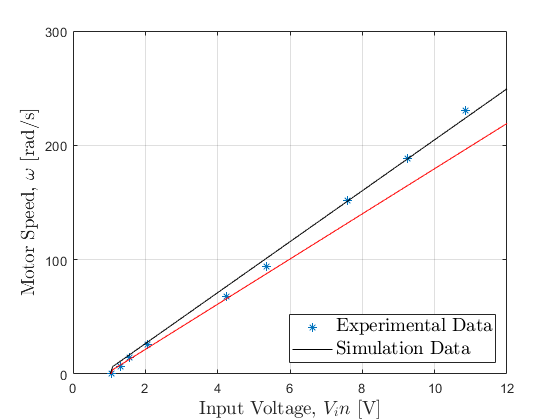

simout = sim('motomatic_pend_OL.slx',2);

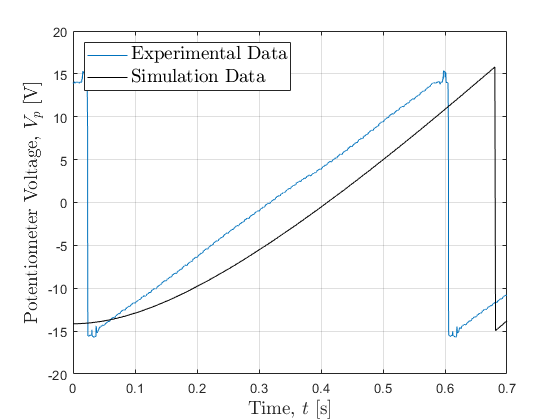

figure;
plot(Vpdata.Time_s_,Vpdata.Math1_V_);
hold on
plot(simout.tout,simout.vp-15,'k');
hold off
grid on; box on;
xlabel('Time, $t$ [s]','Interpreter','Latex','FontSize',14); 
ylabel('Potentiometer Voltage, $V_p$ [V]','Interpreter','Latex','FontSize',14);
xlim([0 0.7]); 
legend('Experimental Data','Simulation Data','location','northwest','fontsize',14);